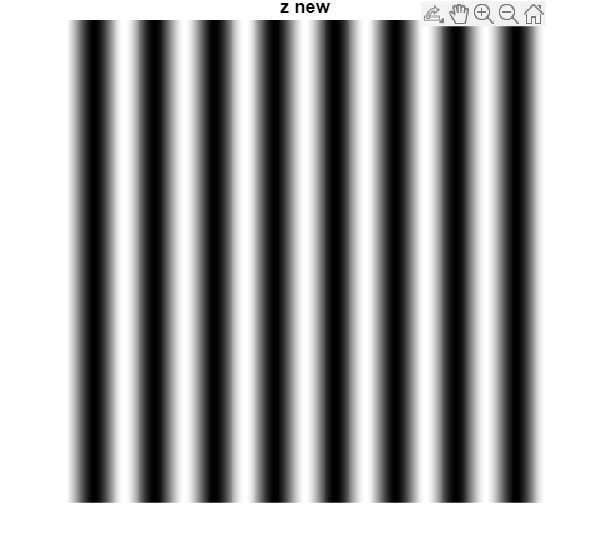

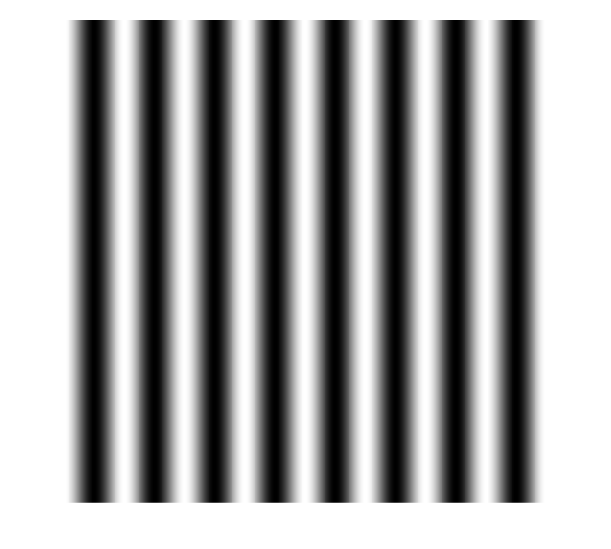

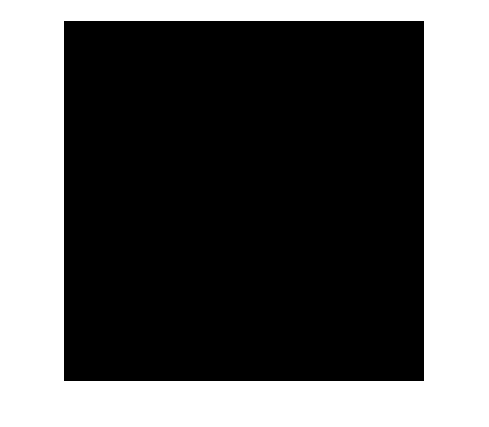

a=0:0.1:16*pi;
a=0:0.1:16*pi;               %設定a的範圍0~16pi，相鄰值間隔0.1
z=zeros(length(a));          %宣告z為大小是length(b)*length(b)的零矩陣
for i=1:length(a)            %for loop，i從1到length(a)
    z(:,i)=a(i);             %將z的每一列第i行的值宣告為a的第i個值
end                          %結束for loop
z_new=(cos(z)+1)/2;          %將cos(z)的值轉換成0~1並宣告為z_new
imshow(z_new)                %在視窗中顯示z_new(左上圖)
zf=fftshift(fft2(z_new));    %宣告zf為z_new的傅立葉轉換
fftshow(zf);                 %用fftshow函數在視窗中顯示zf(左下圖)
b=0:0.1:32*pi;               %宣告b的範圍0~32pi，相鄰值間隔0.1
bb=zeros(length(b));         %宣告bb為大小是length(b)*length(b)的零矩陣
for i=1:length(b)            %for loop，i從1到length(b)
    bb(i,:)=b(i);            %宣告bb的每一行第i列的值為b的第i個值
end                          %結束for loop
bb_new=(cos(bb)+1)/2;        %將cos(bb)的值轉換成0~1並宣告為z_new
imshow(bb_new)               %在視窗中顯示bb_new(右上圖)
bbf=fftshift(fft2(bb_new));%宣告bbf為bb_new的傅立葉轉換
fftshow(bbf);              %用fftshow函式，在視窗中顯示bbf(右上圖)
